clear
clc
close all
a=load('data2.txt')

a =    19.0000   30.0300
   19.5000   30.4800
   20.0000   30.9500
   20.5000   31.4400
   21.0000   31.9500
   21.5000   32.4900
   22.0000   33.0500
   22.5000   33.6300
   23.0000   34.2300
   23.5000   34.8500


%load('newdata2.mat')
lamde=load('lamde.txt')

lamde =     2.0400
    2.1200
    2.2000
    2.2800
    2.3600
    2.4400
    2.5100
    2.5900
    2.6700
    2.7600


Pr=load('Pr.txt')

Pr =     0.7280
    0.7280
    0.7230
    0.7160
    0.7120
    0.7070
    0.7050
    0.7030
    0.7010
    0.6990


vx=load('vx.txt')

vx =    -50
   -40
   -30
   -20
   -10
     0
    10
    20
    30
    40


vy=load('vy.txt')

vy =     9.2300
   10.0400
   10.8000
   11.6100
   12.4300
   13.2800
   14.1600
   15.0600
   16.0000
   16.9600


Prx=vx(6:23);
Pry=Pr(6:23);
lamdex=vx(6:23);
lamdey=lamde(6:23)*1e-2;
vx=vx(6:23)

vx =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


vy=vy(6:23)*1e-6

vy =    1.0e-04 *

    0.1328
    0.1416
    0.1506
    0.1600
    0.1696
    0.1795
    0.1897
    0.2002
    0.2109
    0.2210


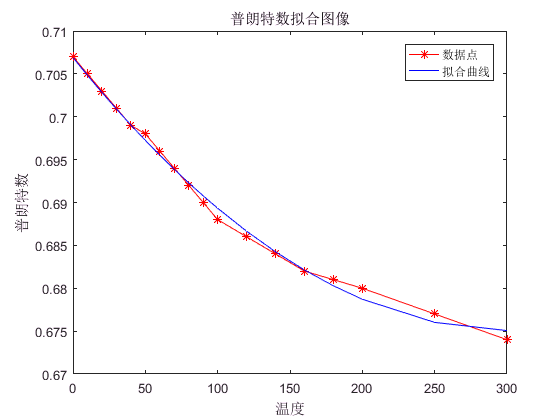


tmpx=Prx;
tmpy=Pry;
plot(tmpx,tmpy,'-r*')
hold on
plot(tmpx,funairPr(tmpx),'-b')
title('普朗特数拟合图像')
xlabel('温度')
ylabel('普朗特数')
legend('数据点','拟合曲线')

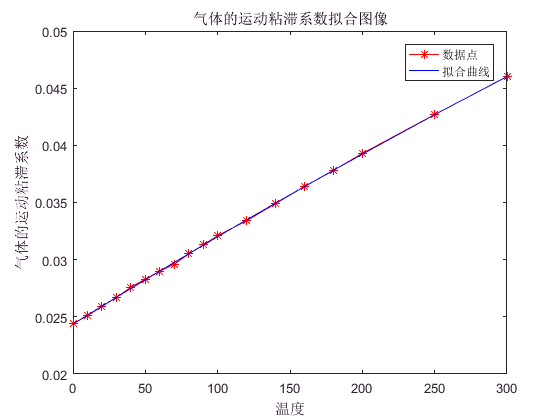

figure


tmpx=lamdex;
tmpy=lamdey;
plot(tmpx,tmpy,'-r*')
hold on
plot(tmpx,funairlamde(tmpx),'-b')
title('气体的运动粘滞系数拟合图像')
xlabel('温度')
ylabel('气体的运动粘滞系数')
legend('数据点','拟合曲线')

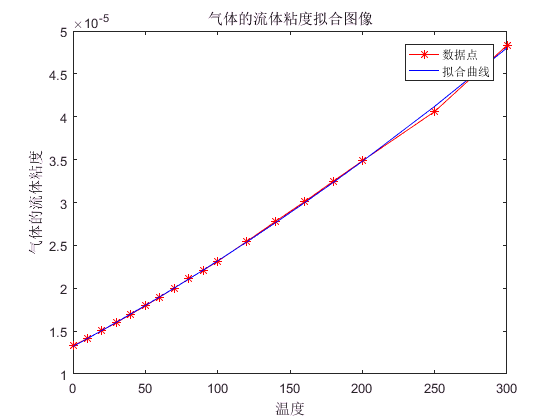

figure

tmpx=vx;
tmpy=vy;
plot(tmpx,tmpy,'-r*')
hold on
plot(tmpx,funairv(tmpx),'-b')
title('气体的流体粘度拟合图像')
xlabel('温度')
ylabel('气体的流体粘度')
legend('数据点','拟合曲线')